# Worksheet 5

In the last worksheet, we examined the stationary heat equation, that is the temperature $T$ was depending on space only. Now, we generalize to the instationary heat equation

$T_t = T_{xx} + T_{yy} $    (1)

on the unit square$\Omega =]0, 1[^2$ for $t \ge  0$ with the temperature $T (x, y)$, the two-dimensional coordinates $x$ and $y$, the time $t$, homogeneous Dirichlet boundary conditions

$T (x, y, t) = 0$ $\forall (x, y) \in  \partial \Omega , t$ in $[0; \infty [$ (2)

and

$T (x, y, 0) = 1.0$ $\forall (x, y) \in ]0; 1[^2$  (3)

as initial condition.

For the spatial discretization, we again use the grid points

$\{(x_i , y_j ) = (i \cdot  h_x , j \cdot  h_y ) , i = 0, 1, . . . , N_x , N_x + 1, j = 0, 1, . . . , N_y , N_y + 1\}$ and the finite difference approximation of the second derivatives

$T_{xx} |_{i,j} \approx \frac {T_{i-1,j} - 2T_{i,j} + T_{i+1,j}}{h^2_x}$ ,


$$T_{yy} |_{i,j} \approx \frac {T_{i,j-1} - 2T_{i,j} + T_{i,j+1}}{h^2_y}$$


for $i = 1, . . . , N_x , j = 1, . . . , N_y$ with $h_x = \frac{1} {N_x+1}$ and $h_y = \frac{1} {N_y+1}$ .

**a)** To have a rough insight into the exact solution of (1), (2), and (3), determine

$ \lim_{t \to \infty} T(x,y,t)$ [...]

**b)** Implement an explicit Euler step for (1) and (2) as a function of the grid sizes $N_x$ and $N_y$, the time step $\delta t$, and the computed solution at the current time.

**c) **

**i)** Solve (1), (2), and (3) with the help of this Euler method for the values of $\delta t$, $N_x$, and $N_y$ listed in the table below.

T = 1;
results = cell(4,4);
i = 1;
for N = 2.^(2:5)-1
    N_x = N;
    N_y = N;
    A = sparse_matrix(N_x, N_y);
    buff = zeros(4, N_x*N_y);
    k = 1;
    for dt = 2.^-(6:12)
        xm = ones(N_x*N_y,1);
        j = 1;
        for t = 0:dt:T
            xm = expl_euler(A, dt, xm);
            if t == 1/8 || t == 2/8 || t == 3/8 || t == 4/8
                buff(j, :) = xm;
                j = j+1;
            end
        end
        results{i,k} = buff;
        k = k+1;
    end
    i = i+1;
end

**ii)** Plot the solutions at times $t = \frac{1}{8}, \frac{2}{8}, \frac{3}{8}, \frac{4}{8}$ as surface plots. Organize your plots into four windows (one per time *t*). Each window should contain the 28 plots from the table below. Besides this, store all 112 plots as images (JPEG or PNG) with meaningful names.

**Note: Do not send the picture files with your submission. Instead, the code should generate the files.**

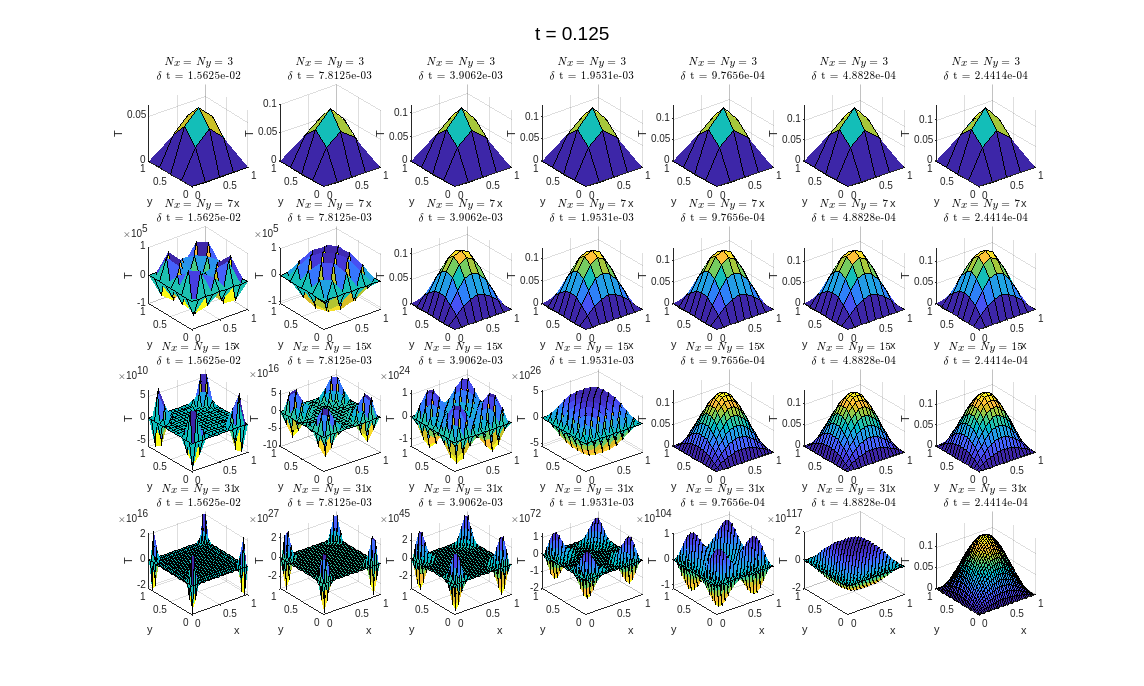

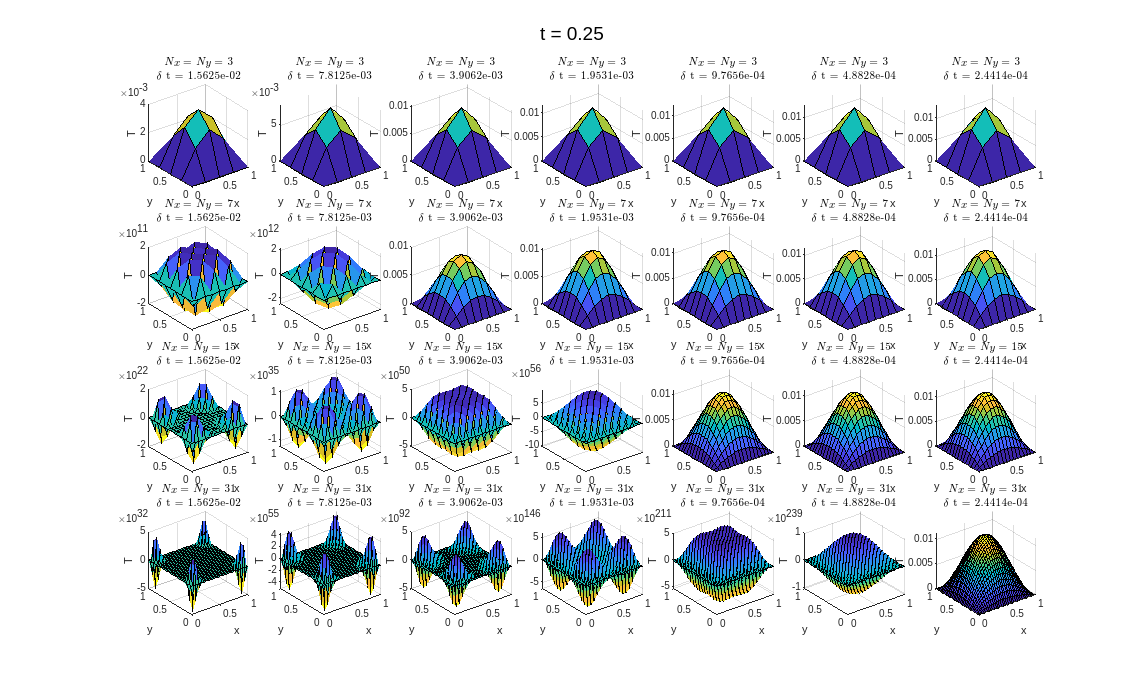

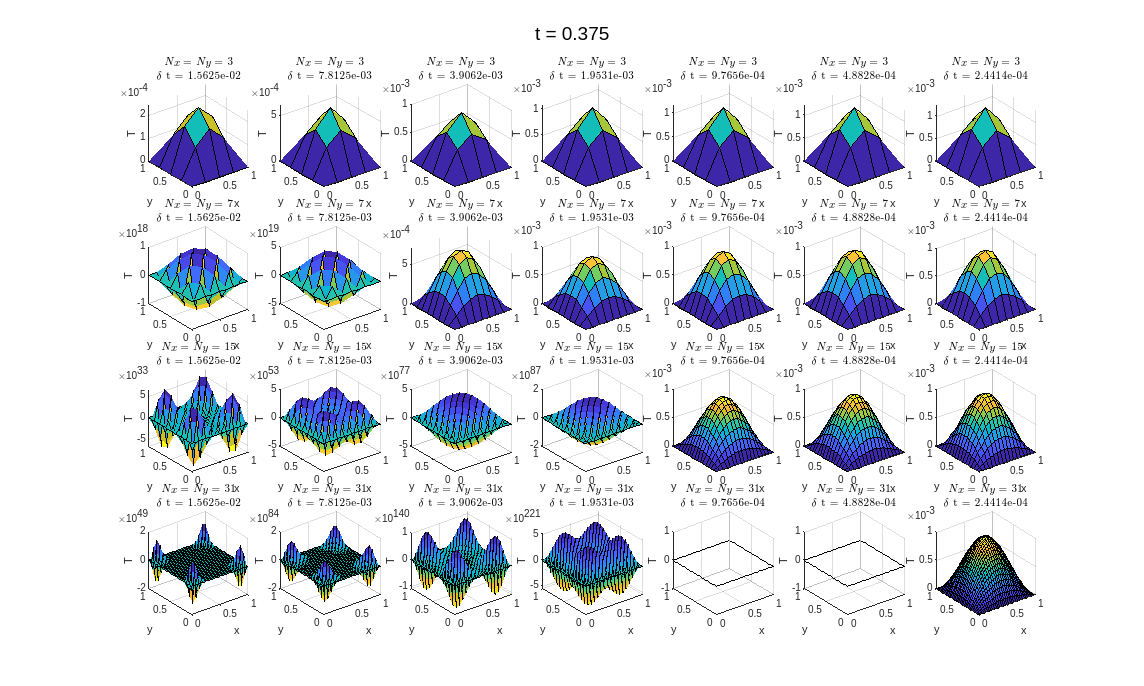

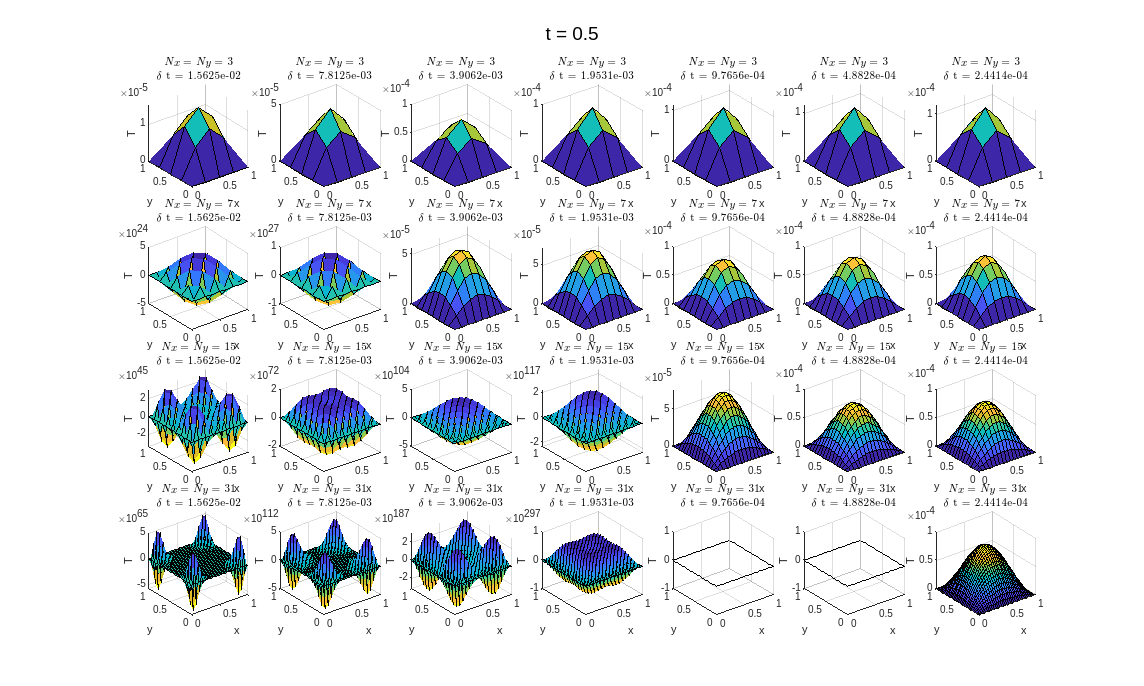

t = (1:4)./8;
dt = 2.^-(6:12);
N = 2.^(2:5)-1;
for j = 1:length(t)
    h = figure;
    for k = 1:length(dt)
        for i = 1:length(N)
            N_x = N(i);
            N_y = N(i);
            span = linspace(0,1,N_x+2);
            subplot(length(N),length(dt),k+(i-1)*length(dt));
            a = results{i,k}(j,:);
            surf(span, span, add_bound(reshape(a, [N_x, N_y]),N_x,N_y));
            title({" ";"$N_x$ = $N_y$ = " + N(i);"$\delta$ t = " + sprintf("%.4e",dt(k))}, 'interpreter', 'latex')
            xlabel('x');
            ylabel('y');
            zlabel('T');
        end
    end
    sgtitle("t = " +t(j))
    set(h,'Position', [0 0 1250 750])
end

**iii)** Mark cases with stable solutions in the table.

stability_table = table(['O' 'X' 'X' 'X']', ['O' 'X' 'X' 'X']', ['O' 'O' 'X' 'X']',...
    ['O' 'O' 'X' 'X']', ['O' 'O' 'O' 'X']', ['O' 'O' 'O' 'X']', ['O' 'O' 'O' 'O']',...
    'rownames', {'3', '7', '15', '31'}, 'VariableNames', ...
    {'dt=1/64', 'dt=1/128', 'dt=1/256','dt=1/512','dt=1/1024','dt=1/2048','dt=1/4096'} );
disp(stability_table)

          dt=1/64    dt=1/128    dt=1/256    dt=1/512    dt=1/1024    dt=1/2048    dt=1/4096
          _______    ________    ________    ________    _________    _________    _________

    3        O          O           O           O            O            O            O    
    7        X          X           O           O            O            O            O    
    15       X          X           X           X            O            O            O    
    31       X          X           X           X            X            X            O    



**Remark 1:** If your simulation is taking too long (more than a couple of minutes on an average laptop) there might be something poorly implemented.

**Remark 2:** In terms of performance, consider whether solving each problem and plotting it take a similar amount of time.

**d)** Implement an implicit Euler step for (1) and (2) as a function of the grid sizes $N_x$ and $N_y$ , the time step $\delta t$, and the computed solution at the current time.

**Hint: **Use a modification of the Gauss-Seidel solver implemented in worksheet 4 for the solution of the system of linear equations in each timestep. Iterate until the norm of the residual is below $10^{-6 }$.

**e)**

**i) **Solve (1), (2), and (3) with the help of the implicit Euler method and time step $\delta t = \frac{1}{64}$ for all spatial resolutions. Do you get stable solutions?

**ii)** Plot the solutions at times $t = \frac{1}{8}, \frac{2}{8}, \frac{3}{8}, \frac{4}{8}$.

T = 1;
results = cell(4,1);
i = 1;
for N = 2.^(2:5)-1
    N_x = N;
    N_y = N;
    A = sparse_matrix(N_x, N_y);
    buff = zeros(4, N_x*N_y);
    k = 1;
    for dt = 2.^-(6)
        xm = ones(N_x*N_y,1);
        j = 1;
        for t = 0:dt:T
            xm = gauss_seidel(xm, N_x, N_y, dt);
            if t == 1/8 || t == 2/8 || t == 3/8 || t == 4/8
                buff(j, :) = xm;
                j = j+1;
            end
        end
        results{i,k} = buff;
        k = k+1;
    end
    i = i+1;
end

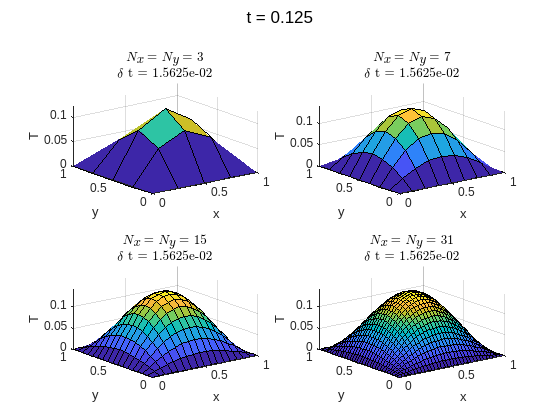

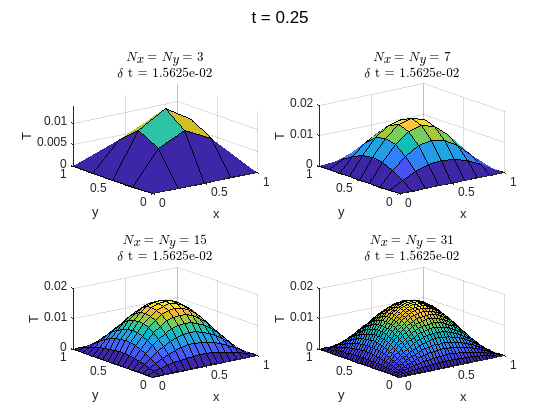

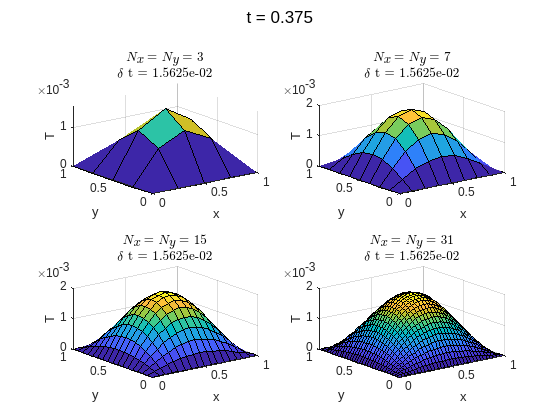

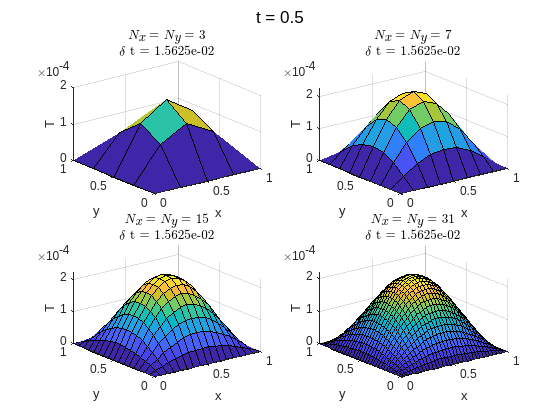

t = (1:4)./8;
dt = 2.^-(6);
N = 2.^(2:5)-1;
for j = 1:length(t)
    h = figure;
    for k = 1:length(dt)
        for i = 1:length(N)
            N_x = N(i);
            N_y = N(i);
            span = linspace(0,1,N_x+2);
            subplot(2,2,k+(i-1)*length(dt));
            a = results{i,k}(j,:);
            surf(span, span, add_bound(reshape(a, [N_x, N_y]),N_x,N_y));
            title({" ";"$N_x$ = $N_y$ = " + N(i);"$\delta$ t = " + sprintf("%.4e",dt(k))}, 'interpreter', 'latex')
            xlabel('x');
            ylabel('y');
            zlabel('T');
        end
    end
    sgtitle("t = " +t(j))
end